## Reading global specs file

filename = 'global_specs.txt';
params = ReadFile(filename);

Non-comment lines:
    {'wav'}    {'inputsignal.wav'}    {'10000'}    {'tone'}    {'20000'}    {'4'}    {'0.5'}    {'100, 200, 300, 400'}    {'1'}    {'rect'}    {'50'}    {'fir'}    {'4'}    {'butterworth'}    {'bp'}    {'1000, 4000'}    {'0.01'}    {'1'}    {'lin'}    {'log'}    {'nyquist'}    {'20'}

Chosen signal:
wav
Filename:
inputsignal.wav
Target sampling frequency:
       10000

Generated signal type:
tone
Generator sampling frequency:
       20000

Generated signal duration:
     4

Spectral resolution:
     1

Window type:
rect
Overlap:
    50

Filtering method:
fir
Filter order:
     4

Approximation method:
butterworth
Filter type:
bp
Cut-off frequencies:
        1000        4000

X-axis time limit:
    0.0100

Y-axis amplitude limit:
     1

X-axis scaling:
lin
Y-axis scaling:
log
X-axis frequency limit:
        5000

Y-axis spectral amplitude limit:
    20



if strcmp(params.chosen_signal,'generate')
    [signal,t]=generate_signal1(params.generator_fs, params.generated_signal_duration, params.generated_signal_type, params.tone_freq, params.periodicity);
Fs=params.generator_fs;
end
if strcmp(params.chosen_signal,'wav')
filePath = 'hum.wav';
[signal, Fs] = audioread(filePath);
signal=resample(signal,params.target_fs,Fs);
Fs=Fs*(floor(numerator)/floor(denominator));
t=0:1/Fs:length(y)*(1/Fs)-(1/Fs);
end


DFT_Y =   -0.0037 + 0.0000i
  -0.0018 + 0.0011i
  -0.0005 - 0.0004i
   0.0025 + 0.0006i
   0.0005 - 0.0014i
  -0.0008 + 0.0002i
  -0.0001 - 0.0011i
   0.0039 + 0.0019i
  -0.0006 + 0.0021i
   0.0002 - 0.0009i


STFT_Y = 1.0e+03 *

   0.0012 - 0.0033i  -0.0005 + 0.0031i  -0.0022 - 0.0031i   0.0015 - 0.0020i   0.0004 + 0.0008i   0.0006 + 0.0020i  -0.0000 + 0.0022i  -0.0019 + 0.0000i   0.0007 - 0.0027i   0.0009 - 0.0014i
  -0.0007 + 0.0005i  -0.0003 + 0.0013i  -0.0006 - 0.0014i   0.0003 - 0.0019i   0.0001 - 0.0001i   0.0000 + 0.0009i   0.0002 + 0.0015i   0.0001 - 0.0005i  -0.0004 - 0.0012i   0.0001 + 0.0003i
  -0.0009 + 0.0003i   0.0007 - 0.0001i   0.0003 - 0.0001i  -0.0004 - 0.0012i   0.0000 + 0.0007i  -0.0004 + 0.0005i   0.0002 + 0.0008i   0.0004 - 0.0003i  -0.0008 - 0.0007i   0.0003 - 0.0002i
  -0.0005 - 0.0005i  -0.0002 - 0.0001i  -0.0002 - 0.0003i   0.0003 - 0.0005i   0.0003 - 0.0001i  -0.0002 + 0.0001i   0.0004 + 0.0003i   0.0004 - 0.0000i  -0.0003 - 0.0004i  -0.0003 - 0.0001i
  -0.0002 - 0.0005i   0.0001 + 0.0007i  -0.0002 - 0.0006i  -0.0001 - 0.0001i   0.0001 - 0.0000i  -0.0003 + 0.0002i   0.0001 + 0.0011i   0.0003 - 0.0008i  -0.0007 - 0.0007i   0.0003 + 0.0001i
  -0.0005 + 0.0003i  -0.0

f_DFT =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


f_STFT =        -4999
       -4998
       -4997
       -4996
       -4995
       -4994
       -4993
       -4992
       -4991
       -4990


## Storing data as ASCII and plots as pdf

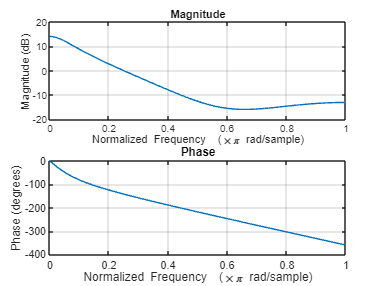

% Example: Filter Coefficients
b = [0.1, 0.15, 0.5, 0.15, 0.1];  % Example filter coefficients (numerator)
a = [1, -0.8];                   % Example filter coefficients (denominator)

% Save numerator coefficients
save('numerator_coefficients.txt', 'b', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'a', '-ascii');

% Example Plot
freqz(b, a);  % Frequency response of the filter

% Save as a PDF with minimal white space
exportgraphics(gcf, 'filter_response.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none');